# Fit Wide Tables in a Page

This example shows how to fit a wide table in a report.

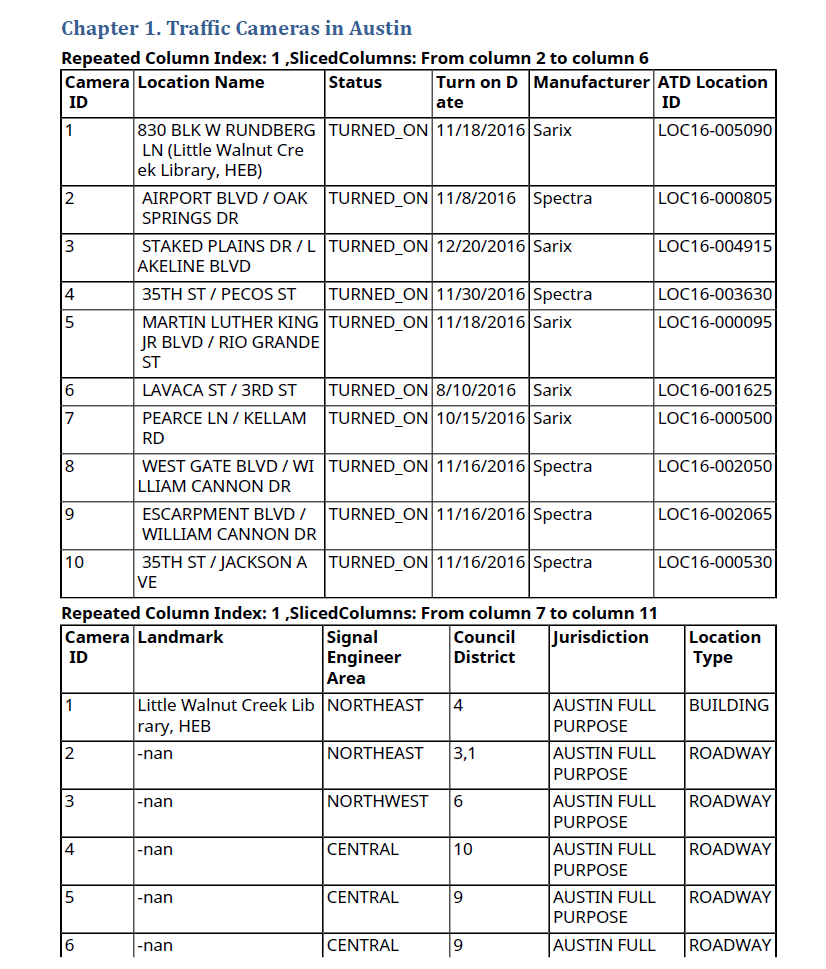

The data for this example is a mat file containing cell array of traffic camera data from Austin, Texas. This cell array contains information such as camera location, its status and the date when it was turned on etc. 

We assume traffic_data.mat file that contains cell array of traffic camera data is in the current working directory. The requirement is to print the table so all of its columns fit on paper that is 8.5 inches wide by 11 inches long, in portrait orientation.

**Create a Table:**

To include a table in a report, use mlreportgen.dom.FormalTable object. This object has a table body and an optional table header and footer.

First, load a mat file containing MATLAB cell array data to workspace. Create a DOM Formal Table object using the cell array data. To make the table easier to read, set the table headings to bold, and add a left margin space between the table column separator and the table content.

load('traffic_data.mat');
tbl_header = traffic_camera_data(1,:);
traffic_camera_data(1,:) = [];

formalTable = mlreportgen.dom.FormalTable(tbl_header,traffic_camera_data);
formalTable.RowSep = "Solid";
formalTable.ColSep = "Solid";
formalTable.Border = "Solid";
formalTable.Header.TableEntriesStyle = [formalTable.Header.TableEntriesStyle,...
    {mlreportgen.dom.Bold(true)}];
formalTable.TableEntriesStyle = [formalTable.TableEntriesStyle,...
    {mlreportgen.dom.InnerMargin("2pt","2pt","2pt","2pt"),...
    mlreportgen.dom.WhiteSpace("preserve")}];

**Trial Number 1**: Add the DOM Formal Table in a default portrait page of size 8.5 inches wide  and 11 inches long.

Import the DOM and Report API packages so you do not have to use long class names.

import mlreportgen.dom.*
import mlreportgen.report.*;

Create a container to hold the report content.

% To create a Word report, change the output type from "pdf" to "docx". 
rpt = Report("TrafficCameraDataPortrait","pdf");

Create a chapter with the title "Traffic Cameras in Austin".

chapter = Chapter("Title","Traffic Cameras in Austin");

Add the created table to the chapter and add the chapter to the report.

add(chapter, formalTable);
add(rpt, chapter);
close(rpt);

**Result**: The generated report includes the table but the table columns are too narrow. Fitting the whole table in a portrait page created a table that is not legible.

**Trial Number 2**: Fit the wide table in a landscape oriented page, which is 11 inches wide by 8.5 inches long.

import mlreportgen.dom.*
import mlreportgen.report.*;
import mlreportgen.utils.*

rpt = Report("TrafficCameraDataLandscape","pdf");
chapter = Chapter("Title","Traffic Cameras in Austin");

Set the report landscape layout to true. Add the table to the chapter.

rpt.Layout.Landscape = true;
add(chapter,formalTable);
add(rpt,chapter);
close(rpt);

**Result**: Although the landscape layout is better than the portrait page report, many columns are not legible and the table is not easy to read.

**Trial Number 3**:  Use the Report Generator TableSlicer utility to slice the input table into multiple slices. Its MaxCols property specifies the maximum number of columns per table slice.

First, try dividing the table into two slices and print them on default 8.5 wide by 11 inch long portrait paper.

import mlreportgen.dom.*
import mlreportgen.report.*;
import mlreportgen.utils.*

rpt = Report("TrafficCameraDataSlicing-1","pdf");
chapter = Chapter("Title","Traffic Cameras in Austin");

Now, create a table slicer object and specify the formal table as an input . The input table has 18 columns, so to create two slices, set the MaxCols property to 9.

The table slicer utility has a slice method which slices the input table and generates mlreportgen.utils.TableSlice objects. These objects have the sliced table and the start and end column indices of the original input table.

slicer = mlreportgen.utils.TableSlicer("Table",formalTable,"MaxCols",9);
slices = slicer.slice();

Use the start and end index to create a customized title. Then add the customized sliced table title and the table slice to the chapter.

for slice = slices
    str = sprintf("From column %d to column %d",slice.StartCol,slice.EndCol);
    para = Paragraph(str);
    para.Bold = true;
    para.Style = [para.Style,{KeepWithNext(true),...
        OuterMargin("0pt","0pt","5pt","0pt")}];
    add(chapter,para);
    add(chapter,slice.Table);
end


Generate and display the report. 

add(rpt,chapter);
close(rpt);

**Result**: The output is better than first two trials, but the table slices are difficult to read and are disconnected from each other.

**Trial Number 4:  **Based on the trial output so far, reduce the MaxCols value to create 4 table slices. Use the RepeatCols property to repeat columns in all the slices. To connect all 4 slices, set the RepeatCols property value to 1 so that the Camera ID column is repeated in every table slice.

import mlreportgen.dom.*
import mlreportgen.report.*;
import mlreportgen.utils.*

rpt = Report("TrafficCameraDataSlicing-2","pdf");
chapter = Chapter("Title","Traffic Cameras in Austin");

Set the MaxCols value to 6 and the RepeatCols value to 1 .

slicer = mlreportgen.utils.TableSlicer("Table",formalTable,"MaxCols",...
    6,"RepeatCols",1);
slices = slicer.slice();

Create a customized title using the start and end index. Add the customized sliced table title and the table slice to the chapter.

for slice = slices
    str = sprintf("Repeated Column Index: %d ,SlicedColumns: From column %d to column %d",...
        slicer.RepeatCols,slice.StartCol, slice.EndCol);
    para = Paragraph(str);
    para.Bold = true;
    para.Style = [para.Style,{KeepWithNext(true),...
        OuterMargin("0pt","0pt","5pt","0pt")}];
    add(chapter,para);
    add(chapter,slice.Table);
end


Generate and display the report. 

add(rpt,chapter);
close(rpt);
rptview(rpt);

**Result: **Output is legible and it satisfies the original requirement to print the table on a portrait page. The input table style, which has bold headers and inner margins that are retained in all the table slices. 

The table tile is customized for the readers to understand the table entries data.

*Copyright 2018 The MathWorks, Inc*